clear; close all;


DataFolder = "F:\YuLab\Work\GPS\Data\";

Animals = [
    "Kennard";
    "Morad"
    "Hana"];
NumAnms = length(Animals);

DataPath = strings(NumAnms, 1);
for i = 1:length(Animals)
    DataPath(i) = fullfile(DataFolder, Animals(i), sprintf("TimingData_%s", Animals(i)));
end

TimingData = cell(NumAnms, 1);
for i = 1:NumAnms
    TimingData{i} = load(DataPath(i));
end

FigFolder = fullfile(DataFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end


FPs = [1 1.5 2];
Ports = ["L", "R"];

hd_categories = [0 .25 .5 2];


## Hold duration and reaction time

band_width = 0.05;

hd_bins = 0:0.001:3;
kde_hd_pdf = @(x) ksdensity(x, hd_bins, 'Function', 'pdf', 'Bandwidth', band_width);


HD_PDFControl = cell(NumAnms, 1);
HD_PDFChemo = cell(NumAnms, 1);

hd_pd_max = 0;
for a = 1:NumAnms
    HD_PDFControl{a} = cellfun(@(x) kde_hd_pdf(x), TimingData{a}.hd_control, 'UniformOutput', false);
    HD_PDFChemo{a} = cellfun(@(x) kde_hd_pdf(x), TimingData{a}.hd_chemo, 'UniformOutput', false);

    hd_pd_max = max([hd_pd_max max(max(cellfun(@(x1, x2) max([x1 x2]), HD_PDFControl{a}, HD_PDFChemo{a})))]);
end
hd_pd_ylim = ceil(hd_pd_max);


HD_PDFControlMean = cell(3, 2);
HD_PDFChemoMean = cell(3, 2);

for fp = 1:3
    for p = 1:2
        pd_control_this = cellfun(@(x) x{fp, p}, HD_PDFControl, 'UniformOutput', false);
        pd_control_this = cell2mat(pd_control_this);
        HD_PDFControlMean{fp, p} = mean(pd_control_this, 1);

        pd_chemo_this = cellfun(@(x) x{fp, p}, HD_PDFChemo, 'UniformOutput', false);
        pd_chemo_this = cell2mat(pd_chemo_this);
        HD_PDFChemoMean{fp, p} = mean(pd_chemo_this, 1);
    end
end

HD_PDFControlMean2 = cell(3, 1);
HD_PDFChemoMean2 = cell(3, 1);

for fp = 1:3
    HD_PDFControlMean2{fp} = mean([HD_PDFControlMean{fp, 1}; HD_PDFControlMean{fp, 2}]);
    HD_PDFChemoMean2{fp} = mean([HD_PDFChemoMean{fp, 1}; HD_PDFChemoMean{fp, 2}]);
end


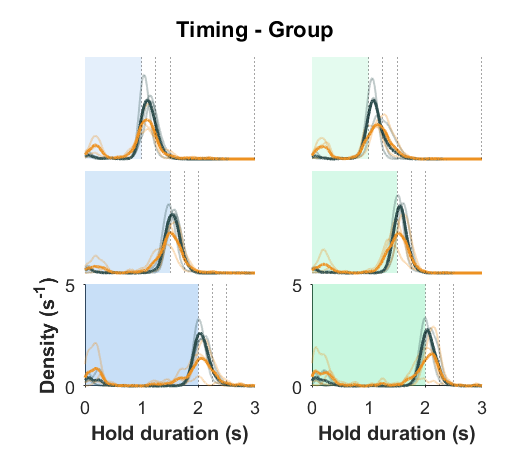

fig_timing = figure(41); clf(fig_timing);
set(fig_timing, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 9 8], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_timing, sprintf("Timing - Group"), 'FontSize', 11);

ax_hd_s = cell(3,2);
ax_hd_pd = cell(3,2);
ax_rt_pd = cell(3,2);

ax_w = 3; ax_h = 1.8;
ax_w_sep = 1; ax_h_sep = .2;

for fp = 1:3
    for p = 1:2
        % Hold duration PDF
        ax_hd_pd{fp, p} = axes(fig_timing, "Units", "centimeters", "Position", [1.5+(p-1)*(ax_w_sep+ax_w) 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
            'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

        xline(ax_hd_pd{fp, p}, FPs(fp)+hd_categories, 'LineWidth', .5, 'Color', 'k', 'LineStyle', ':');

        fill(ax_hd_pd{fp, p}, [0 FPs(fp) FPs(fp) 0], [0 0 hd_pd_ylim hd_pd_ylim], 'r', ...
            'EdgeColor', 'none', 'FaceColor', GPSColor.("Port"+Ports(p)), 'FaceAlpha', 0.3*FPs(fp)/max(FPs));
        for i = 1:NumAnms
            plot(ax_hd_pd{fp, p}, hd_bins, HD_PDFControl{i}{fp, p}, 'Color', [GPSColor.Control .3], 'LineWidth', 1);
            plot(ax_hd_pd{fp, p}, hd_bins, HD_PDFChemo{i}{fp, p}, 'Color', [GPSColor.Treat .3], 'LineWidth', 1);
        end

        plot(ax_hd_pd{fp, p}, hd_bins, HD_PDFControlMean{fp, p}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
        plot(ax_hd_pd{fp, p}, hd_bins, HD_PDFChemoMean{fp, p}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);

        set(ax_hd_pd{fp, p}, 'XLim', [0 3], 'YLim', [0 hd_pd_ylim], 'YTick', [0 hd_pd_ylim]);
        switch fp
            case 3
                ax_hd_pd{fp, p}.XLabel.String = "Hold duration (s)";
                ax_hd_pd{fp, p}.XLabel.FontWeight = "bold";
                if p==1
                    ax_hd_pd{fp, p}.YLabel.String = "Density (s^{-1})";
                    ax_hd_pd{fp, p}.YLabel.FontWeight = "bold";
                end
            otherwise
                set(ax_hd_pd{fp, p}, 'XColor', 'none', 'YColor', 'none');
        end

    end
end

fig_name = sprintf("Test_Distr_Timing_Group_Bi.jpg");
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_timing, fig_path, 'Resolution', 600);

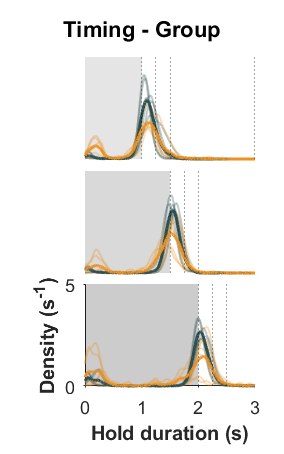

fig_timing2 = figure(42); clf(fig_timing2);
set(fig_timing2, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 5 8], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_timing2, sprintf("Timing - Group"), 'FontSize', 11);

ax_hd_pd2 = cell(3,1);
ax_rt_pd2 = cell(3,1);

ax_w = 3; ax_h = 1.8;
ax_w_sep = 1; ax_h_sep = .2;

for fp = 1:3
    % Hold duration PDF
    ax_hd_pd2{fp} = axes(fig_timing2, "Units", "centimeters", "Position", [1.5 1.2+(3-fp)*(ax_h_sep+ax_h) ax_w ax_h], ...
        'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

    xline(ax_hd_pd2{fp}, FPs(fp)+hd_categories, 'LineWidth', .5, 'Color', 'k', 'LineStyle', ':');
    fill(ax_hd_pd2{fp}, [0 FPs(fp) FPs(fp) 0], [0 0 hd_pd_ylim hd_pd_ylim], 'r', ...
            'EdgeColor', 'none', 'FaceColor', 'k', 'FaceAlpha', 0.2*FPs(fp)/max(FPs));
    for p = 1:2
        for i = 1:NumAnms
            plot(ax_hd_pd2{fp}, hd_bins, HD_PDFControl{i}{fp, p}, 'Color', [GPSColor.Control .3], 'LineWidth', 1);
            plot(ax_hd_pd2{fp}, hd_bins, HD_PDFChemo{i}{fp, p}, 'Color', [GPSColor.Treat .3], 'LineWidth', 1);
        end
    end

    plot(ax_hd_pd2{fp}, hd_bins, HD_PDFControlMean2{fp}, 'Color', GPSColor.Control, 'LineWidth', 1.5);
    plot(ax_hd_pd2{fp}, hd_bins, HD_PDFChemoMean2{fp}, 'Color', GPSColor.Treat, 'LineWidth', 1.5);

    set(ax_hd_pd2{fp}, 'XLim', [0 3], 'YLim', [0 hd_pd_ylim], 'YTick', [0 hd_pd_ylim]);
    switch fp
        case 3
            ax_hd_pd2{fp}.XLabel.String = "Hold duration (s)";
            ax_hd_pd2{fp}.XLabel.FontWeight = "bold";
            ax_hd_pd2{fp}.YLabel.String = "Density (s^{-1})";
            ax_hd_pd2{fp}.YLabel.FontWeight = "bold";
        otherwise
            set(ax_hd_pd2{fp}, 'XColor', 'none', 'YColor', 'none');
    end
end

fig_name = sprintf("Test_Distr_Timing_Group2_Bi.jpg");
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_timing2, fig_path, 'Resolution', 600);

Params = [
    "dMedian"
    "dIQR"
    ];

Func = {
    @(x) median(x, 'omitnan');
    @iqr;
    };


HDStat = cell(NumAnms, 1);

n_boot = 1000;
alpha_ci = 0.05;

for a = 1:NumAnms
    for i = 1:length(Params)
        HDStat{a}.(Params(i)) = cell(3,2);
        HDStat{a}.(Params(i)+"CI") = cell(3,2);
    end
    for fp = 1:3
        for p = 1:2

            hd_control = TimingData{a}.hd_control{fp, p};
            hd_chemo = TimingData{a}.hd_chemo{fp, p};

            for i = 1:length(Params)
                dParam_hat = Func{i}(hd_chemo) - Func{i}(hd_control);

                param_control_boot = bootstrp(n_boot, Func{i}, hd_control);
                param_chemo_boot = bootstrp(n_boot, Func{i}, hd_chemo);
                dParam_boot = param_chemo_boot - param_control_boot;
                dParam_boot_ci = [2*dParam_hat-quantile(dParam_boot, 1-alpha_ci/2) 2*dParam_hat-quantile(dParam_boot, alpha_ci/2)];

                HDStat{a}.(Params(i)){fp, p} = dParam_hat;
                HDStat{a}.(Params(i)+"CI"){fp, p} = dParam_boot_ci;
            end
        end
    end
end


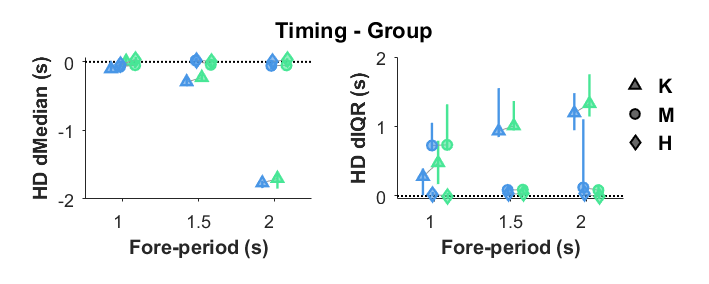

fig_stat = figure(43); clf(fig_stat);
set(fig_stat, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12.5 5], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_stat, sprintf("Timing - Group"), 'FontSize', 11);

ax_hd_stat = cell(1, 2);

ax_w = 4; ax_h = 2.5;
ax_w_sep = 1.5; ax_h_sep = .2;

MarkerSize = 24;
AnmMarker = ["^", "o", "d"];
AnmID = ["K", "M", "H"];
AnmJitter = (rand(1, 3)-.5) / 5;
for i = 1:length(Params)
    ax_hd_stat{i} = axes(fig_stat, "Units", "centimeters", "Position", [1.5+(i-1)*(ax_w_sep+ax_w) 1.5 ax_w ax_h], ...
        'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
    plot(ax_hd_stat{i}, [.5 3.5], [0 0], 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');
    for a = 1:NumAnms
        for fp = 1:3
            plot(ax_hd_stat{i}, fp+[-.1 .1]+AnmJitter(a), cell2mat(HDStat{a}.(Params(i))(fp,:)), 'Color', [.6 .6 .6], 'LineWidth', .5);
            for p = 1:2
                scatter(ax_hd_stat{i}, fp+.1*(-1)^p+AnmJitter(a), HDStat{a}.(Params(i)){fp, p}, MarkerSize, GPSColor.("Port"+Ports(p)), "filled", AnmMarker(a), ...
                    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, ...
                    'MarkerEdgeColor', 'flat', 'LineWidth', 1.2);
                plot(ax_hd_stat{i}, [fp fp]+.1*(-1)^p+AnmJitter(a), HDStat{a}.(Params(i)+"CI"){fp, p}, ...
                    'Color', GPSColor.("Port"+Ports(p)), 'LineWidth', 1.2);
            end
        end
    end
    set(ax_hd_stat{i}, 'XLim', [.5 3.5], 'XTick', 1:3, 'XTickLabel', [1 1.5 2]);
    ax_hd_stat{i}.XLabel.String = "Fore-period (s)";
    ax_hd_stat{i}.XLabel.FontWeight = "bold";
    ax_hd_stat{i}.YLabel.String = "HD "+Params(i)+" (s)";
    ax_hd_stat{i}.YLabel.FontWeight = "bold";

end

ax_legend = axes(fig_stat, "Units", "centimeters", "Position", [11.2 2 2 2], ...
        'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'XColor', 'none', 'YColor', 'none', 'YDir', 'reverse');
for a = 1:NumAnms
    scatter(ax_legend, 1, a, MarkerSize, 'k', 'filled', AnmMarker(a), ...
        'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, ...
        'MarkerEdgeColor', 'flat', 'LineWidth', 1);
    text(ax_legend, 1.2, a, AnmID(a), 'FontWeight', 'bold');
end
set(ax_legend, 'XLim', [1 2], 'YLim', [0 4]);

fig_name = sprintf("Test_Stat_Timing_Group_Bi.jpg");
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_stat, fig_path, 'Resolution', 600);

HDStat_v = cell(NumAnms, 1);

n_boot = 1000;
alpha_ci = 0.05;

for a = 1:NumAnms
    for i = 1:length(Params)
        HDStat_v{a}.(Params(i)) = cell(3,2);
        HDStat_v{a}.(Params(i)+"CI") = cell(3,2);
    end
    for fp = 1:3
        for p = 1:2

            hd_control = TimingData{a}.hd_control_v{fp, p};
            hd_chemo = TimingData{a}.hd_chemo_v{fp, p};

            for i = 1:length(Params)
                dParam_hat = Func{i}(hd_chemo) - Func{i}(hd_control);

                param_control_boot = bootstrp(n_boot, Func{i}, hd_control);
                param_chemo_boot = bootstrp(n_boot, Func{i}, hd_chemo);
                dParam_boot = param_chemo_boot - param_control_boot;
                dParam_boot_ci = [2*dParam_hat-quantile(dParam_boot, 1-alpha_ci/2) 2*dParam_hat-quantile(dParam_boot, alpha_ci/2)];

                HDStat_v{a}.(Params(i)){fp, p} = dParam_hat;
                HDStat_v{a}.(Params(i)+"CI"){fp, p} = dParam_boot_ci;
            end
        end
    end
end


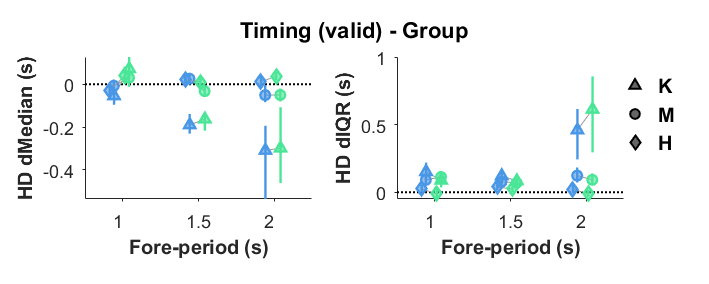

fig_stat_v = figure(44); clf(fig_stat_v);
set(fig_stat_v, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12.5 5], 'Color', 'w', 'toolbar', 'none');

set_fig_title(fig_stat_v, sprintf("Timing (valid) - Group"), 'FontSize', 11);

ax_hd_stat_v = cell(1, 2);

ax_w = 4; ax_h = 2.5;
ax_w_sep = 1.5; ax_h_sep = .2;

MarkerSize = 24;
AnmMarker = ["^", "o", "d"];
AnmID = ["K", "M", "H"];
AnmJitter = (rand(1, 3)-.5) / 5;
for i = 1:length(Params)
    ax_hd_stat_v{i} = axes(fig_stat_v, "Units", "centimeters", "Position", [1.5+(i-1)*(ax_w_sep+ax_w) 1.5 ax_w ax_h], ...
        'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');
    plot(ax_hd_stat_v{i}, [.5 3.5], [0 0], 'LineWidth', 1, 'LineStyle', ':', 'Color', 'k');
    for a = 1:NumAnms
        for fp = 1:3
            plot(ax_hd_stat_v{i}, fp+[-.1 .1]+AnmJitter(a), cell2mat(HDStat_v{a}.(Params(i))(fp,:)), 'Color', [.6 .6 .6], 'LineWidth', .5);
            for p = 1:2
                scatter(ax_hd_stat_v{i}, fp+.1*(-1)^p+AnmJitter(a), HDStat_v{a}.(Params(i)){fp, p}, MarkerSize, GPSColor.("Port"+Ports(p)), "filled", AnmMarker(a), ...
                    'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, ...
                    'MarkerEdgeColor', 'flat', 'LineWidth', 1.2);
                plot(ax_hd_stat_v{i}, [fp fp]+.1*(-1)^p+AnmJitter(a), HDStat_v{a}.(Params(i)+"CI"){fp, p}, ...
                    'Color', GPSColor.("Port"+Ports(p)), 'LineWidth', 1.2);
            end
        end
    end
    set(ax_hd_stat_v{i}, 'XLim', [.5 3.5], 'XTick', 1:3, 'XTickLabel', [1 1.5 2]);
    ax_hd_stat_v{i}.XLabel.String = "Fore-period (s)";
    ax_hd_stat_v{i}.XLabel.FontWeight = "bold";
    ax_hd_stat_v{i}.YLabel.String = "HD "+Params(i)+" (s)";
    ax_hd_stat_v{i}.YLabel.FontWeight = "bold";

end

ax_legend = axes(fig_stat_v, "Units", "centimeters", "Position", [11.2 2 2 2], ...
        'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out', 'XColor', 'none', 'YColor', 'none', 'YDir', 'reverse');
for a = 1:NumAnms
    scatter(ax_legend, 1, a, MarkerSize, 'k', 'filled', AnmMarker(a), ...
        'MarkerFaceColor', 'flat', 'MarkerFaceAlpha', .6, ...
        'MarkerEdgeColor', 'flat', 'LineWidth', 1);
    text(ax_legend, 1.2, a, AnmID(a), 'FontWeight', 'bold');
end
set(ax_legend, 'XLim', [1 2], 'YLim', [0 4]);

fig_name = sprintf("Test_Stat_Timing_v_Group_Bi.jpg");
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig_stat_v, fig_path, 'Resolution', 600);